# 创建一个硅TB模型并拟合参数

## 创建一个硅TB模型并拟合参数

Si = HR.from_POSCAR_SE('POSCAR_All',...
'WAN_NUM',18,...
'Type','mat',...
'alpharule',2,...
'onsite',true,...
'search_range' ,[2 2 2],...
'r_max',10,...
'overlap',true,...
'level_cut',-1);

Generating 18/18 th orb nn information ...
Giving nn_level for 26869/26892 th hopping  ...

错误使用 string/strcat (第 37 行)
所有非标量输入的大小必须相同。

出错 HR/alpharule (第 3002 行)
            V_n_list = sym(strcat(V_n_str_L,repmat('_',[(level_cut-1)*N_base_string,1]),level_cut_str_L),'real');

出错 HR.from_POSCAR_SE (

### 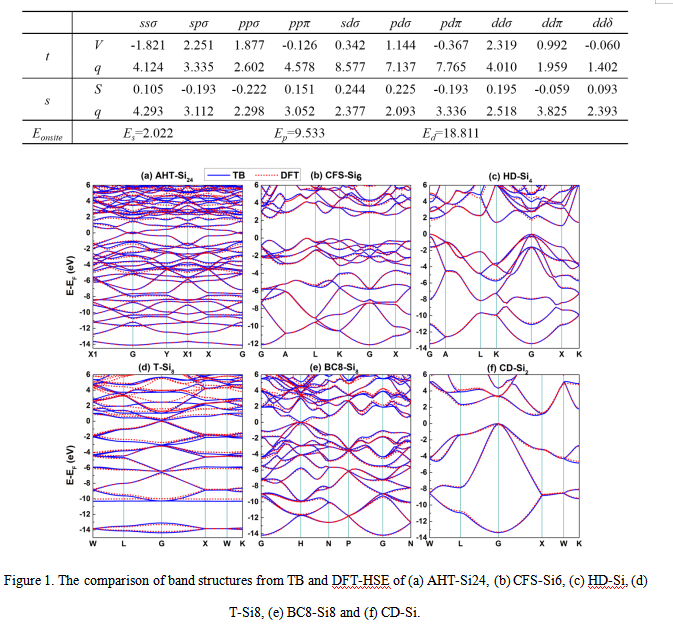

     ssS           *spS*  ppS      ppP  *sdS*         pdS     pdP    *ddS*  *ddP*   *ddD* 

*V*  -1.821  2.251  1.877  -0.126  0.342  1.144  -0.367  2.319  0.992  -0.060 

*q*  4.124  3.335  2.602  4.578  8.577  7.137  7.765  4.010  1.959  1.402 

S  0.105  -0.193  -0.222  0.151  0.244  0.225  -0.193  0.195  -0.059  0.093 

*q*  4.293  3.112  2.298  3.052  2.377  2.093  3.336  2.518  3.825  2.393 

 -2.022  　  　  9.533  　  　   18.811  　  　  　 

### 赋值

Vhopping = Si.symvar_list

Soverlap = symvar(Si.ScoeL)


E_onsite  = [ -2.022,9.533,18.811];
Vhopping_n = [-0.060	0.992	2.319	-0.367	1.144	-0.126	1.877	0.342	2.251	-1.821];
Valpha_n = [1.402	4.124	3.335	8.577	2.602	7.137	4.578	7.765	4.010	1.959];
Soverlap_n = [0.093	-0.059	0.195	-0.193	0.225	0.151	-0.222	0.244	-0.193	0.105];
Salpha_n = [2.393	4.293	3.112	2.377	2.298	2.093	3.052	3.336	2.518	3.825];

Si.ScoeL = subs(Si.ScoeL,Soverlap,[Soverlap_n,Salpha_n]);
Si_n = Si.subs(Vhopping,[E_onsite,Vhopping_n,Valpha_n]);

EIGENCAR = Si_n.EIGENCAR_gen();
bandplot(EIGENCAR,[-14,6]);


### 读取DFT能带

EIGENCAR_DFT = EIGENVAL_read();
bandplot(EIGENCAR_DFT,[-14,6]);